# Image Category Classification Using Bag of Features

This example shows how to use a bag of features approach for image category classification. This technique is also often referred to as bag of words. Visual image categorization is a process of assigning a category label to an image under test. Categories may contain images representing just about anything, for example, dogs, cats, trains, boats.

## Load Image Dataset

Unzip a collection of images to use for this example.  

% unzip('MerchData.zip');

Load the image collection using an `imageDatastore` to help you manage the data. Because `imageDatastore` operates on image file locations, and therefore does not load all the images into memory, it is safe to use on large image collections. 

imds = imageDatastore('MerchData','IncludeSubfolders',true,'LabelSource','foldernames');

You can easily inspect the number of images per category as well as category labels as shown below:

tbl = countEachLabel(imds)

tbl = 5×2 table
             Label             Count
    _______________________    _____

    MathWorks Cap               15  
    MathWorks Cube              15  
    MathWorks Playing Cards     15  
    MathWorks Screwdriver       15  
    MathWorks Torch             15  


Note that the labels were derived from directory names used to construct the ImageDatastore, but can be customized by manually setting the Labels property of the ImageDatastore object. Next, display a few of the images to get a sense of the type of images being used.

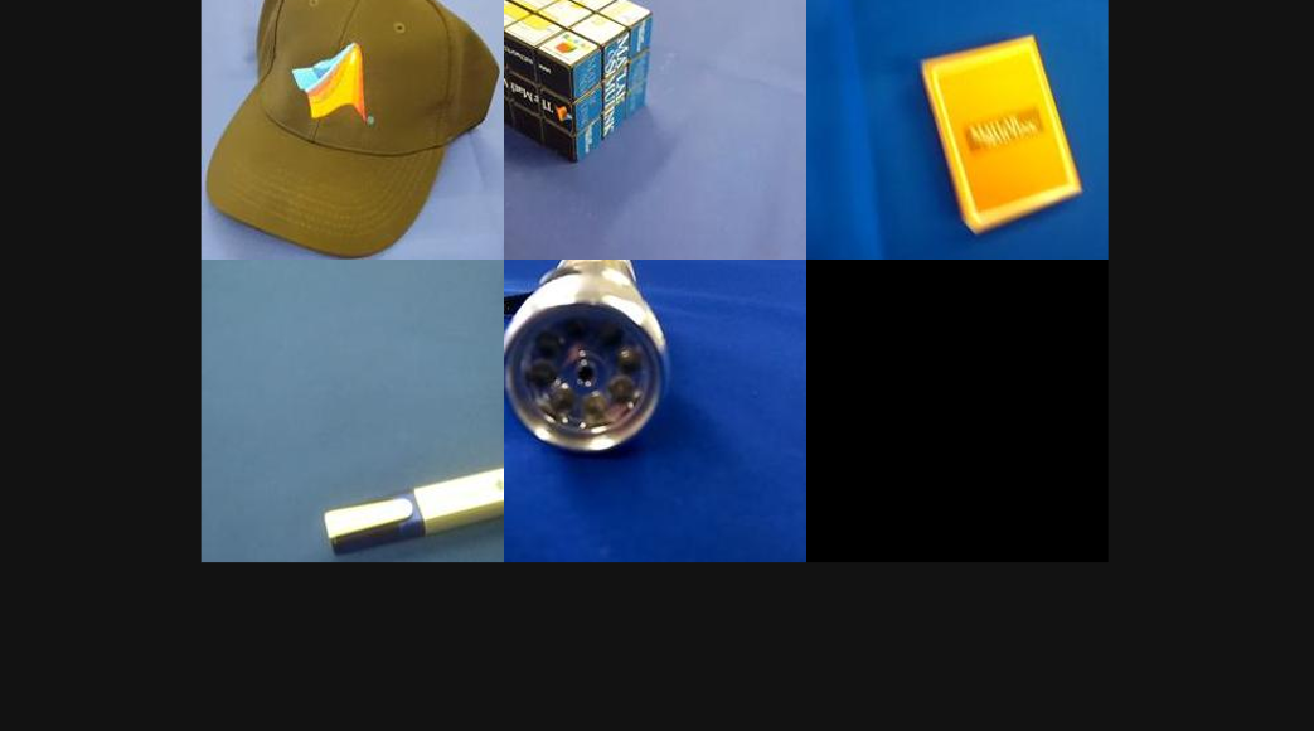

figure
montage(imds.Files(1:16:end))

Note that for the bag of features approach to be effective, the majority of the object must be visible in the image.

## Prepare Training and Validation Image Sets

Separate the sets into training and validation data. Pick 60% of images from each set for the training data and the remainder, 40%, for the validation data. Randomize the split to avoid biasing the results.

[trainingSet, validationSet] = splitEachLabel(imds, 0.7, 'randomize');


Creating Bag-Of-Features.
-------------------------
* Image category 1: MathWorks Cap
* Image category 2: MathWorks Cube
* Image category 3: MathWorks Playing Cards
* Image category 4: MathWorks Screwdriver
* Image category 5: MathWorks Torch
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 55 images...done. Extracted 172480 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 137985
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 56/100 iterations (~1.13 seconds/iteration)...converged in 56 iterations.

* Finished creating Bag-Of-Features



The above call returns two imageDatastore objects ready for training and validation tasks. 

## Create a Visual Vocabulary and Train an Image Category Classifier

Bag of words is a technique adapted to computer vision from the world of natural language processing. Since images do not actually contain discrete words, we first construct a "vocabulary" of [SURF](docid:vision_ref#bsxmas0) features representative of each image category.

This is accomplished with a single call to `bagOfFeatures` function, which:

- extracts SURF features from all images in all image categories

- constructs the visual vocabulary by reducing the number of features through quantization of feature space using K-means clustering

bag = bagOfFeatures(trainingSet);

Additionally, the bagOfFeatures object provides an `encode` method for counting the visual word occurrences in an image. It produced a histogram that becomes a new and reduced representation of an image.

img = readimage(imds, 1);


Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


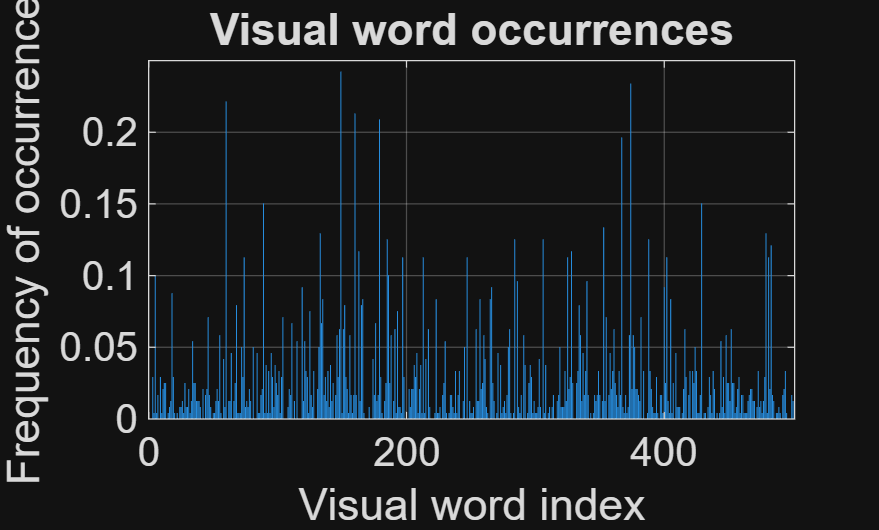

featureVector = encode(bag, img);

% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')

ylabel('Frequency of occurrence')


Training an image category classifier for 5 categories.
--------------------------------------------------------
* Category 1: MathWorks Cap
* Category 2: MathWorks Cube
* Category 3: MathWorks Playing Cards
* Category 4: MathWorks Screwdriver
* Category 5: MathWorks Torch

* Encoding features for 55 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



This histogram forms a basis for training a classifier and for the actual image classification. In essence, it encodes an image into a feature vector. 

Encoded training images from each category are fed into a classifier training process invoked by the `trainImageCategoryClassifier` function. Note that this function relies on the multiclass linear SVM classifier from the Statistics and Machine Learning Toolbox™.

categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);


Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: MathWorks Cap
* Category 2: MathWorks Cube
* Category 3: MathWorks Playing Cards
* Category 4: MathWorks Screwdriver
* Category 5: MathWorks Torch

* Evaluating 55 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                                                          PREDICTED
KNOWN                      | MathWorks Cap   MathWorks Cube   MathWorks Playing Cards   MathWorks Screwdriver   MathWorks Torch   
----------------------------------------------------------------------------------------------------------------------------------
MathWorks Cap              | 1.00            0.00             0.00                      0.00                    0.00              
MathWorks Cube             | 0.00            1.00             0.00                      0.00                    0.00           

The above function utilizes the `encode` method of the input `bag` object to formulate feature vectors representing each image category from the  `trainingSet`.

## Evaluate Classifier Performance

Now that we have a trained classifier, `categoryClassifier`, let's evaluate it. As a sanity check, let's first test it with the training set, which should produce near perfect confusion matrix, i.e. ones on the diagonal.

confMatrix = evaluate(categoryClassifier, trainingSet);


Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: MathWorks Cap
* Category 2: MathWorks Cube
* Category 3: MathWorks Playing Cards
* Category 4: MathWorks Screwdriver
* Category 5: MathWorks Torch

* Evaluating 20 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                                                          PREDICTED
KNOWN                      | MathWorks Cap   MathWorks Cube   MathWorks Playing Cards   MathWorks Screwdriver   MathWorks Torch   
----------------------------------------------------------------------------------------------------------------------------------
MathWorks Cap              | 0.75            0.00             0.25                      0.00                    0.00              
MathWorks Cube             | 0.00            0.75             0.00                      0.00                    0.25           

Next, let's evaluate the classifier on the validationSet, which was not used during the training. By default, the `evaluate` function returns the confusion matrix, which is a good initial indicator of how well the classifier is performing.

confMatrix = evaluate(categoryClassifier, validationSet);

% Compute average accuracy

ans = 0.8000

mean(diag(confMatrix))

You can tune `bagOfFeatures` hyperparameters and continue evaluating the trained classifier until you are satisfied with the results. Additional statistics can be derived using the rest of arguments returned by the evaluate function. See help for `imageCategoryClassifier/evaluate`. 

## Try the Newly Trained Classifier on Test Images

You can now apply the newly trained classifier to categorize new images.

img = imread(fullfile('MerchData','MathWorks Cap','Hat_0.jpg'));
  ind = randi(numel(validationSet.Files));
img = readimage(validationSet, ind);


Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


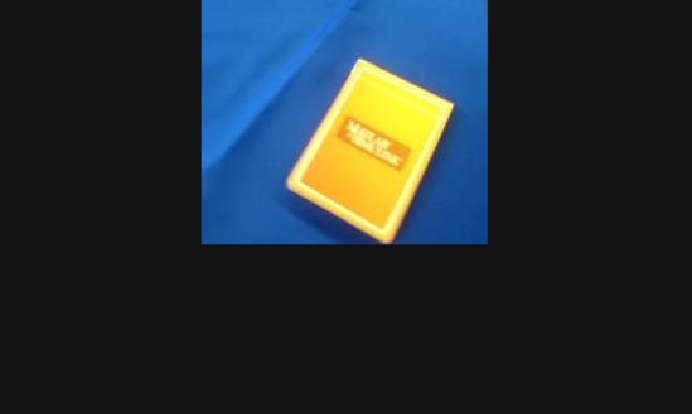

[labelIdx, scores] = predict(categoryClassifier, img);

figure

imshow(img)

MathWorks Playing Cards


disp(string(categoryClassifier.Labels(labelIdx)))